%Il codice non è statto ancora testato sulla sequenza di 401 campioni
%

## START

close all
clear
clc
%prompt = ('Inserisci nome file :  ');
%nome_file = input (prompt, 's');
%load (nome_file);
load zerointerleaving.mat
dim = length(x);
M = input('Inserisci M: ');
P = -1; %P permette di scegliere la pos del primo campione non nullo
while (P < 0 || P > M)
    P = input('\n\nInserisci la posizione del primo campione non nullo (0-M):  ');
end
f_s = 1/M; %frequenza di campionamento, ma potremmo toglierla perché non serve
a_x = 'Campioni';

## **ZERO-INTERLEAVING**

y_n = zeros(M,dim); %crea una matrice di zeri contenente le M sequenze lungo le righe
Yf_n = y_n; %copia la matrice creata in quella che sarà la trasformata
for j = 1:M %ciclo per creare M sequenze zero-interleaved
    i = j;
    while i<dim+1
        y_n(j,i) = x(i);
        i = i+M;
    end
end

## **TRASFORMAZIONI** 

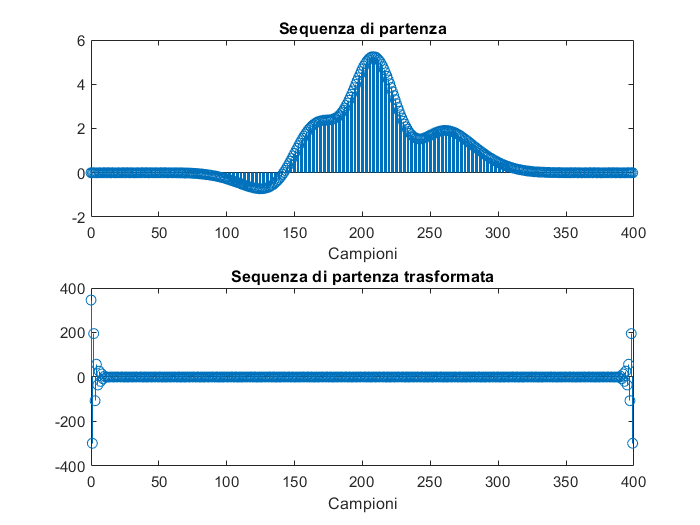

n = (0:dim-1);
Xf=fft(x);
figure
subplot(2,1,1)
stem (n,x);
xlabel (a_x)
title('Sequenza di partenza')
%pause
subplot(2,1,2)
stem (n,real(Xf));
xlabel (a_x)
title('Sequenza di partenza trasformata')

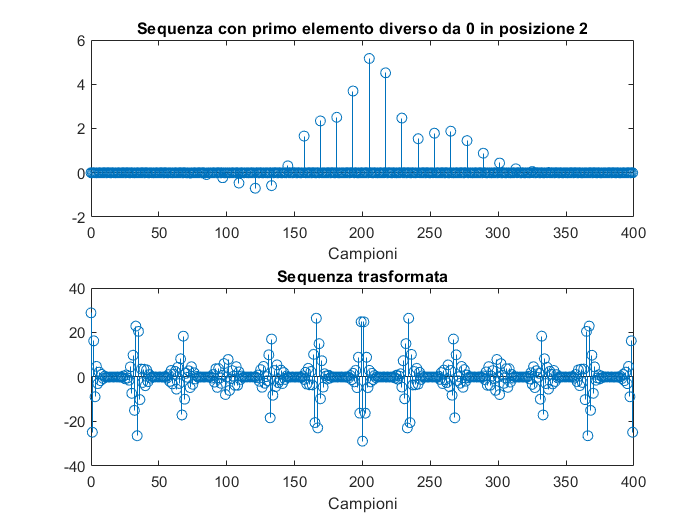

%pause
titolo = 'Sequenza con primo elemento diverso da 0 in posizione %d';
%indice di posizione che viene riportato nel grafico
Yf_n(P,:) = fft(y_n(P,:));
figure
subplot(2,1,1)
stem(n,y_n(P,:));
xlabel (a_x)
title(sprintf(titolo,P))
subplot(2,1,2)
stem(n,real(Yf_n(P,:)));
xlabel (a_x)
title('Sequenza trasformata')

%pause

## **FILTRO**

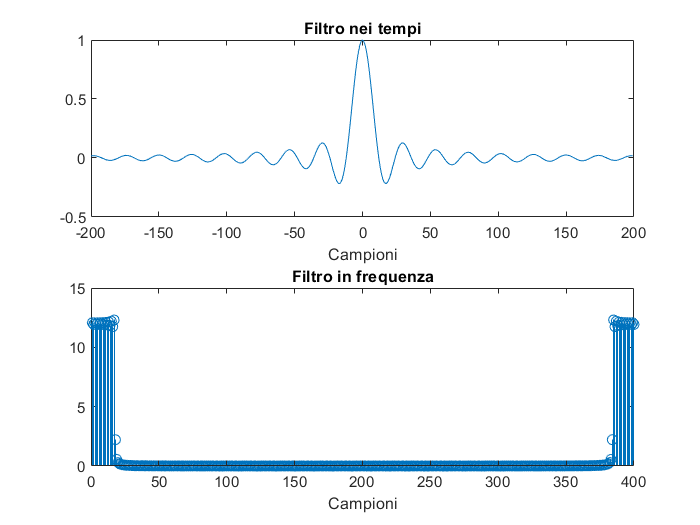

figure
t=-dim/2:dim/2-1;
filtro_t=sinc(t/M);
filtro=abs(fft(filtro_t));
subplot (2,1,1)
plot(t,filtro_t);
title('Filtro nei tempi')
xlabel (a_x)
subplot (2,1,2)
stem(filtro);
title('Filtro in frequenza')
xlabel (a_x)

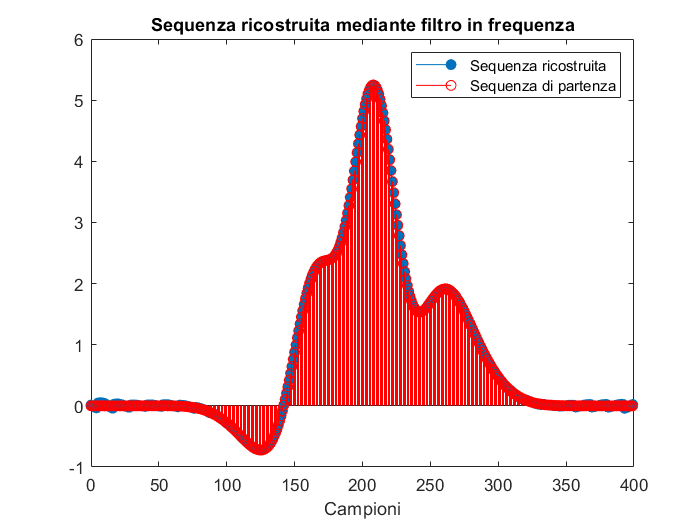

%pause
Zf_n=zeros(M,dim);
z=zeros(M,(2*dim)-1);
u=zeros(M,dim);
%errorequadraticotempo=zeros(M,dim);
figure
%figure(3)
Zf_n(P,:) = Yf_n(P,:).*filtro;
z(P,:) = conv(y_n(P,:),filtro_t);
u(P,:) = z(P,(dim/2)+1:(3/2)*dim); %range di campioni utili della sequenza ricostruita
errorequadratico=immse(x(1,:),u(P,:));
%subplot(2,1,1)
stem(n,u(P,:),'filled','DisplayName','Sequenza ricostruita');
xlabel (a_x)
title('Sequenza di partenza e ricostruita')
legend
%title('Sequenza ricostruita mediante filtro nei tempi')
%subplot(2,1,2)
hold on
stem (n,x,'r','DisplayName','Sequenza di partenza');
%xlabel ('Campioni')
%title('Sequenza di Partenza')
%stem(abs(errorequadraticotempo(i,:)));
hold off
%subplot(3,1,3);
%stem(real(Zf_n(i,:)));
title('Sequenza ricostruita mediante filtro in frequenza')

%pause
format shortE;
output = 'Errore quadratico medio = %d \n';
fprintf(output,errorequadratico)

Errore quadratico medio = 1.168790e-04 


if errorequadratico > 1.0e-03
    output = 'Errore quadratico medio superiore al limite! \n\n';
    fprintf(output)
end

## **GRAFICO M - MSE**

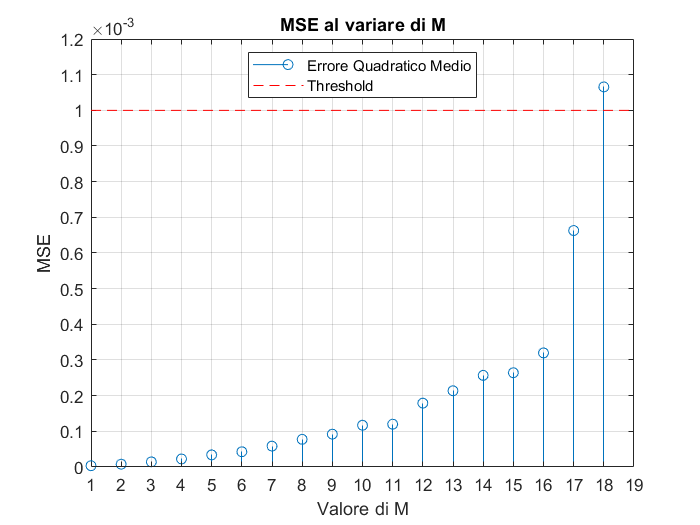

%Il grafico riporta la relazione tra M ed MSE fino al primo valore di M
%che supera la soglia proposta dal professore
M = 1;
P = 1;
k = 1;
errorequadratico = -1;
mse = zeros(1,dim);
%Il ciclo while viene ripetuto finche' M non causa un MSE troppo alto
%Potrebbe essere implementato in modo tale da ripetersi per M che arriva
%fino a DIM, ma mi sembra esagerato; allo stesso modo non vedo il motivo
%ne il fondamento teorico per fissare un valore di M a priori
%questo algoritmo e' adattabile a ogni valore di soglia per MSE
%NOTA: P non puo' essere il valore immesso all'inizio dall'utente
%perche' ci possono essere casi in cui M<P nei primi passi dell'algoritmo
%Dal codice di Progetto_zero_interleaving risulta che MSE varia a seconda di
%P, ma sono variazioni nell' ODG di 10^-6 che non fanno variare
%l'andamento complessivo del grafico M-MSE
while errorequadratico < 1.0e-03 
    M = M+1;
    y_n = zeros(M,dim); %crea una matrice di zeri contenente le M sequenze lungo le righe
    Yf_n = y_n; %copia la matrice creata in quella che sarà la trasformata
    for j = 1:M %ciclo per creare M sequenze zero-interleaved
        i = j;
        while i<dim+1
            y_n(j,i) = x(i);
            i = i+M;
        end
    end
    Xf=fft(x);
    Yf_n(P,:) = fft(y_n(P,:));
    t=-dim/2:dim/2-1;
    filtro_t=sinc(t/M);
    filtro=abs(fft(filtro_t));
    Zf_n=zeros(M,dim);
    z=zeros(M,(2*dim)-1);
    u=zeros(M,dim);
    Zf_n(P,:) = Yf_n(P,:).*filtro;
    z(P,:) = conv(y_n(P,:),filtro_t);
    u(P,:) = z(P,(dim/2)+1:(3/2)*dim); %range di campioni utili della sequenza ricostruita
    errorequadratico = immse(x(1,:),u(P,:));
    mse(k) = errorequadratico;
    k = k+1;
end
mse_t = zeros(1,M);
threshold = zeros(1,M);
for i = 1:M
    mse_t(i) = mse(i);
    threshold (i) = 1e-03;
end
mse_t(i) = NaN;
stem(mse_t,'DisplayName','Errore Quadratico Medio');
title('MSE al variare di M')
xlim ([1 M])
xticks (1:1:M)
yticks (0:1e-04:1.2e-03)
xlabel('Valore di M')
ylabel('MSE')
grid on
hold on
plot (threshold,'r','LineStyle','--','DisplayName','Threshold')
legend('Location','North')